# Lab04_Assignment

## Student Number    : 20180808045

## Name Lastname    : Arda Atasoy

### Assignment Description

There are 3 tables in Population.mat file that consist of countries and their populations in every 5 year since 1960. 

- PopulationTotal has total pupulations.

- PopulationFemale has female populations.

- PopulationMale has male populations.

Annotations (title, xlabel, ylabel) are important!

#### Load Data

clear
clc
load Populations.mat

#### Task 1 - BAR GRAPH

Pick 5 countries and visualize their total populations for all given years by using only one bar graph.

Sample output: 

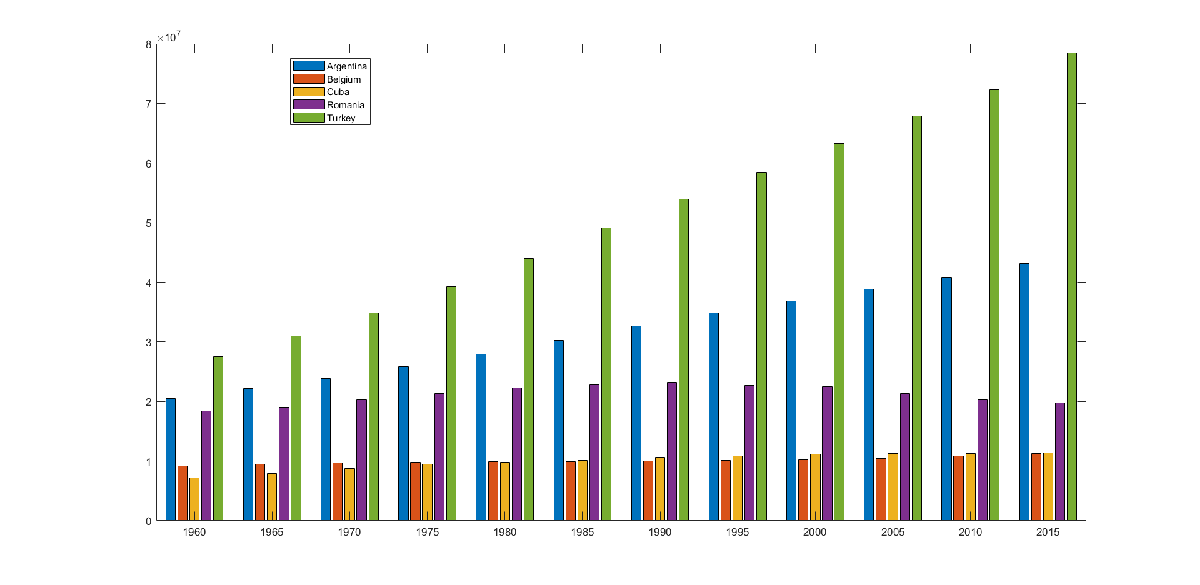

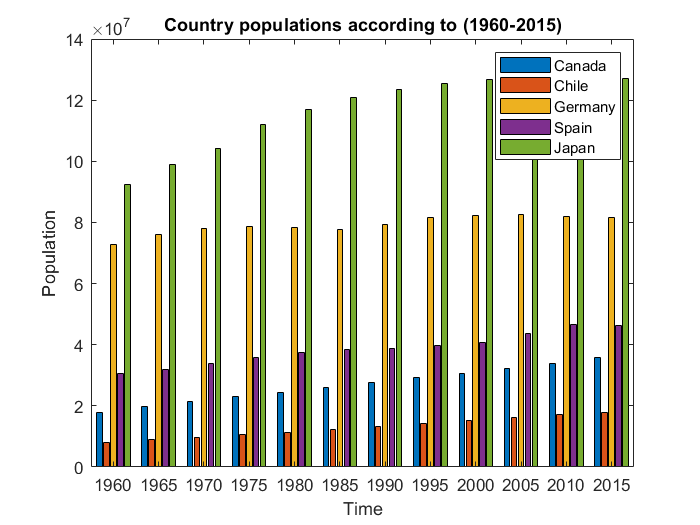

totalP=PopulationsTotal([30,33,47,54,89],4:15);
totalP=table2array(totalP);
totalP=totalP';
x=1960:5:2015;
bar(x,totalP);
legend("Canada","Chile","Germany","Spain","Japan");
xlabel('Time');
ylabel("Population");
title("Country populations according to (1960-2015)")

#### Task 2 - PIE CHART

Visualize female and male populations by using pie charts for the countries you've selected.

Make pie chart only for the years 2015, 2000, 1985, 1970

Each country should have it's own figure. You must split each figure to 4 (2 by 2) by using **subplot**(2,2,x) command. 

Sample output: There will be 5 figures sth like in the sample

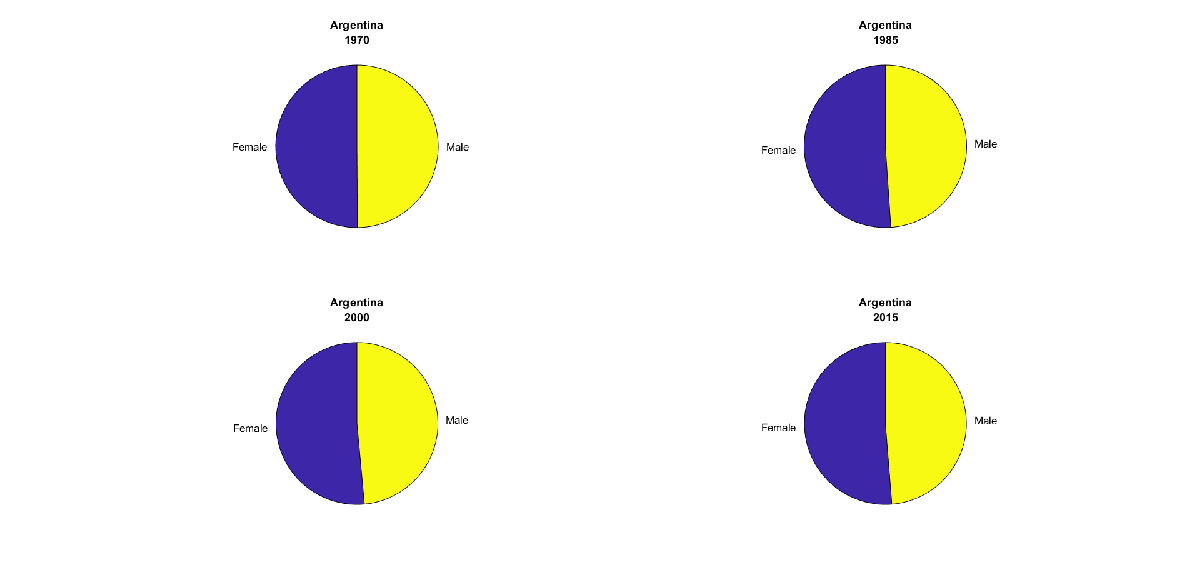

totalFemale=PopulationsFemale([30,33,47,54,89],[6,9,12,15]);
totalFemale=table2array(totalFemale);
totalMale=PopulationsMale([30,33,47,54,89],[6,9,12,15]);
totalMale=table2array(totalMale);

CanadaPie1970=[totalMale(1,1) ,totalFemale(1,1)];
CanadaPie1985=[totalMale(1,2) ,totalFemale(1,2)];
CanadaPie2000=[totalMale(1,3) ,totalFemale(1,3)];
CanadaPie2015=[totalMale(1,4) ,totalFemale(1,4)];
labels={'Male','Female'}

labels = 1×2 cell array
    {'Male'}    {'Female'}


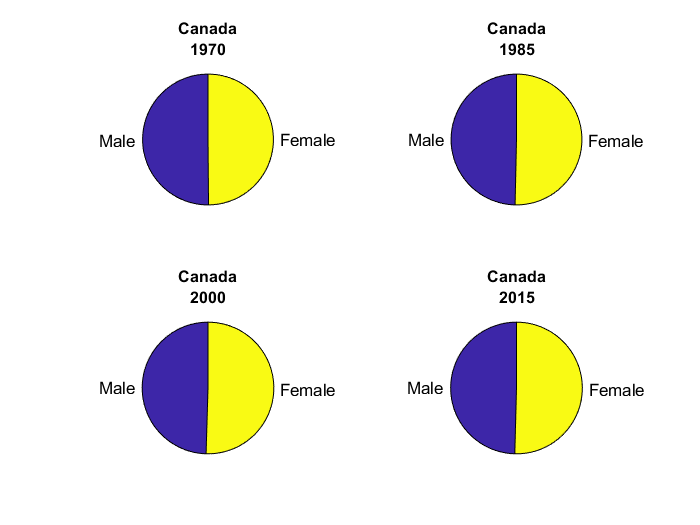


subplot(2,2,1)
pie(CanadaPie1970,labels);
title({'Canada';'1970'})
subplot(2,2,2)
pie(CanadaPie1985,labels);
title({'Canada';'1985'})
subplot(2,2,3)
pie(CanadaPie2000,labels);
title({'Canada';'2000'})
subplot(2,2,4)
pie(CanadaPie2015,labels);
title({'Canada';'2015'})

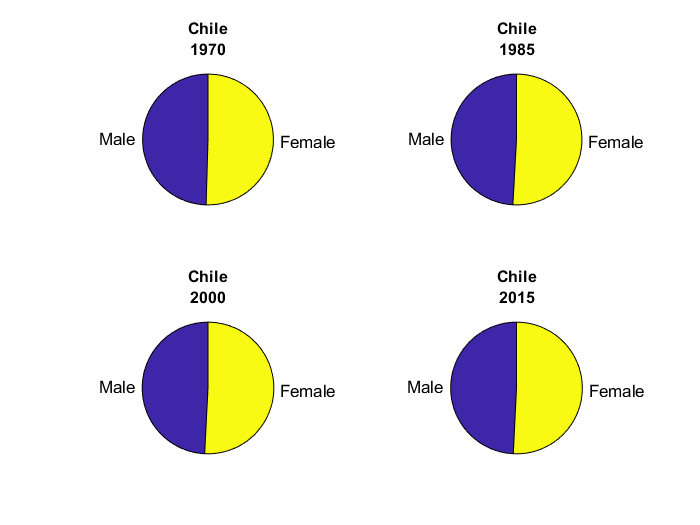

ChilePie1970=[totalMale(2,1) ,totalFemale(2,1)];
ChilePie1985=[totalMale(2,2) ,totalFemale(2,2)];
ChilePie2000=[totalMale(2,3) ,totalFemale(2,3)];
ChilePie2015=[totalMale(2,4) ,totalFemale(2,4)];
subplot(2,2,1)
pie(ChilePie1970,labels);
title({'Chile';'1970'})
subplot(2,2,2)
pie(ChilePie1985,labels);
title({'Chile';'1985'})
subplot(2,2,3)
pie(ChilePie2000,labels);
title({'Chile';'2000'})
subplot(2,2,4)
pie(ChilePie2015,labels);
title({'Chile';'2015'})

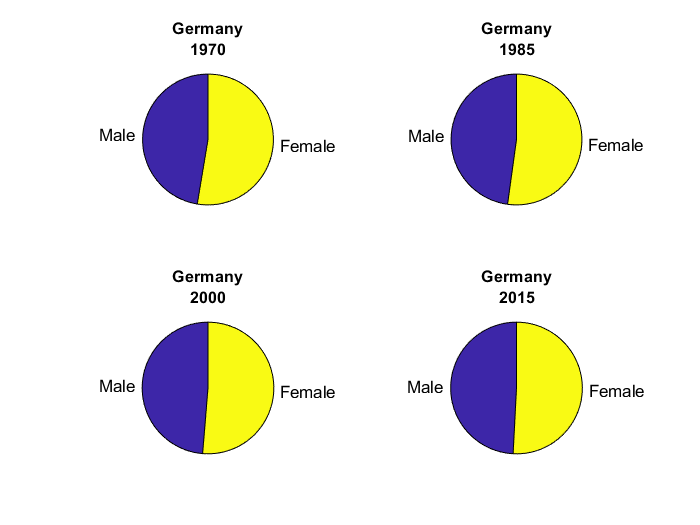

GermanyPie1970=[totalMale(3,1) ,totalFemale(3,1)];
GermanyPie1985=[totalMale(3,2) ,totalFemale(3,2)];
GermanyPie2000=[totalMale(3,3) ,totalFemale(3,3)];
GermanyPie2015=[totalMale(3,4) ,totalFemale(3,4)];
subplot(2,2,1)
pie(GermanyPie1970,labels);
title({'Germany';'1970'})
subplot(2,2,2)
pie(GermanyPie1985,labels);
title({'Germany';'1985'})
subplot(2,2,3)
pie(GermanyPie2000,labels);
title({'Germany';'2000'})
subplot(2,2,4)
pie(GermanyPie2015,labels);
title({'Germany';'2015'})

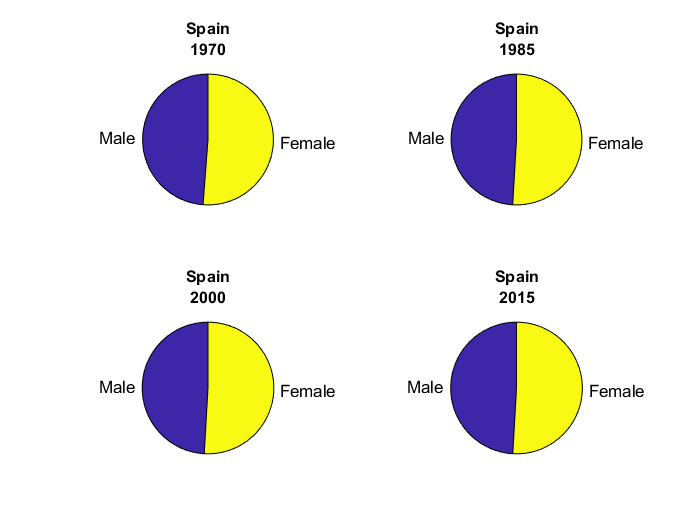

SpainPie1970=[totalMale(4,1) ,totalFemale(4,1)];
SpainPie1985=[totalMale(4,2) ,totalFemale(4,2)];
SpainPie2000=[totalMale(4,3) ,totalFemale(4,3)];
SpainPie2015=[totalMale(4,4) ,totalFemale(4,4)];
subplot(2,2,1)
pie(SpainPie1970,labels);
title({'Spain';'1970'})
subplot(2,2,2)
pie(SpainPie1985,labels);
title({'Spain';'1985'})
subplot(2,2,3)
pie(SpainPie2000,labels);
title({'Spain';'2000'})
subplot(2,2,4)
pie(SpainPie2015,labels);
title({'Spain';'2015'})

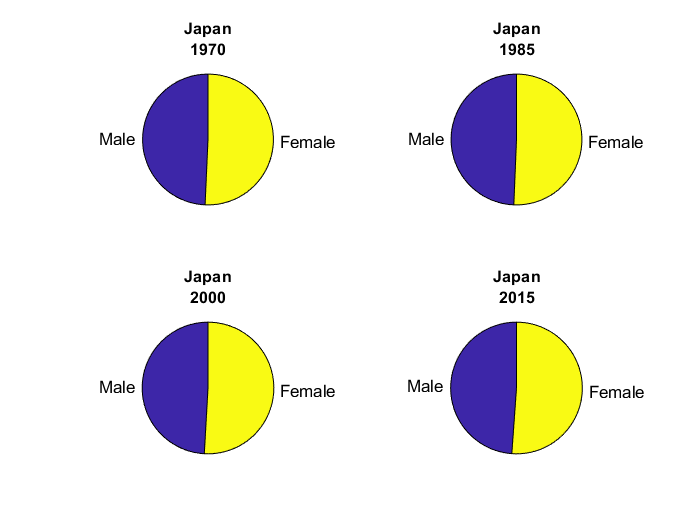

JapanPie1970=[totalMale(5,1) ,totalFemale(5,1)];
JapanPie1985=[totalMale(5,2) ,totalFemale(5,2)];
JapanPie2000=[totalMale(5,3) ,totalFemale(5,3)];
JapanPie2015=[totalMale(5,4) ,totalFemale(5,4)];
subplot(2,2,1)
pie(JapanPie1970,labels);
title({'Japan';'1970'})
subplot(2,2,2)
pie(JapanPie1985,labels);
title({'Japan';'1985'})
subplot(2,2,3)
pie(JapanPie2000,labels);
title({'Japan';'2000'})
subplot(2,2,4)
pie(JapanPie2015,labels);
title({'Japan';'2015'})



figure




#### Task 3 - BOX PLOT

Plot the box plot of total populations. 

PS: You must use populations of all the countries.

Sample figure:

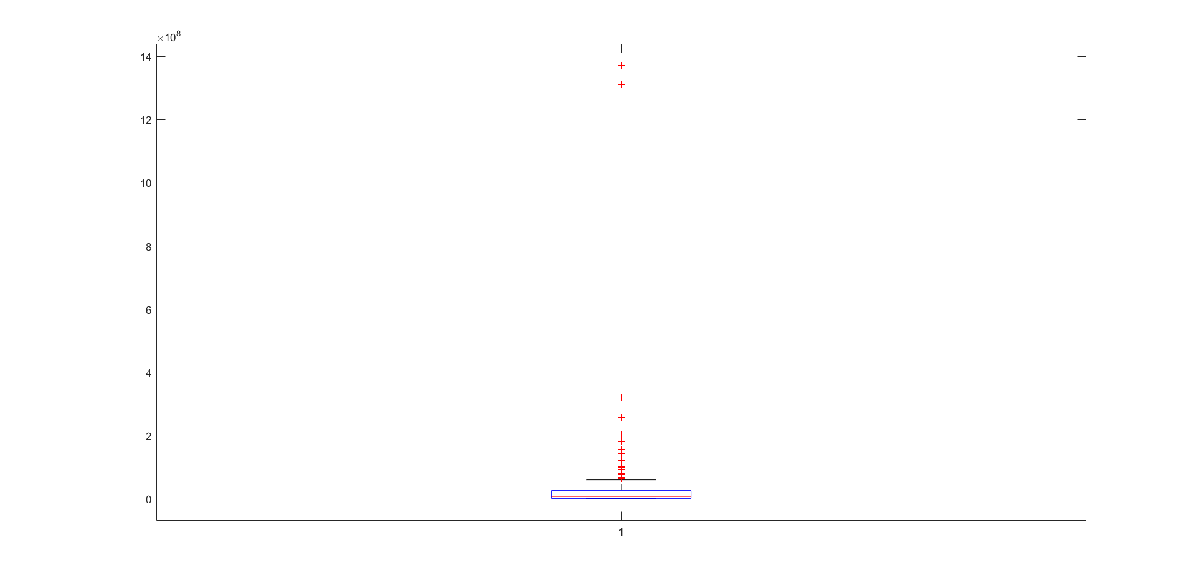

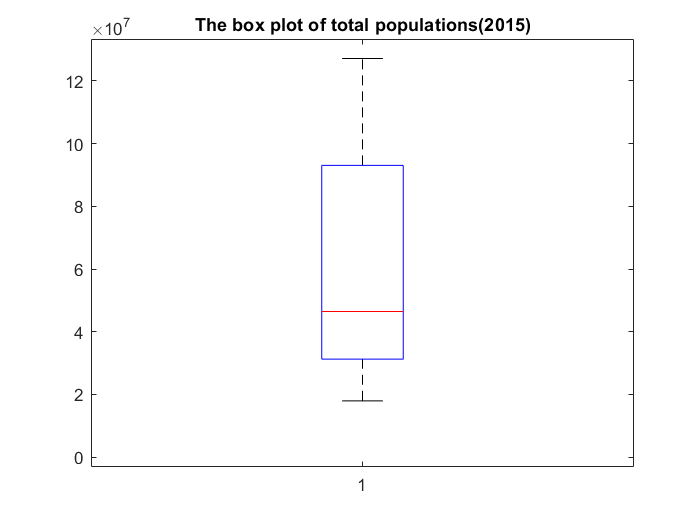

totalP3=totalP(12,:);
sortcount=sort(totalP3);
mediancount=median(totalP3);
q1count=quantile(totalP3,0.25);
q3count=quantile(totalP3,0.75);
mincount=min(totalP3);
maxcount=max(totalP3);
boxplot(totalP3);
title("The box plot of total populations(2015)")

#### Task 4 - BOX PLOT

Plot box plots of total populations for every region.

Sample figure

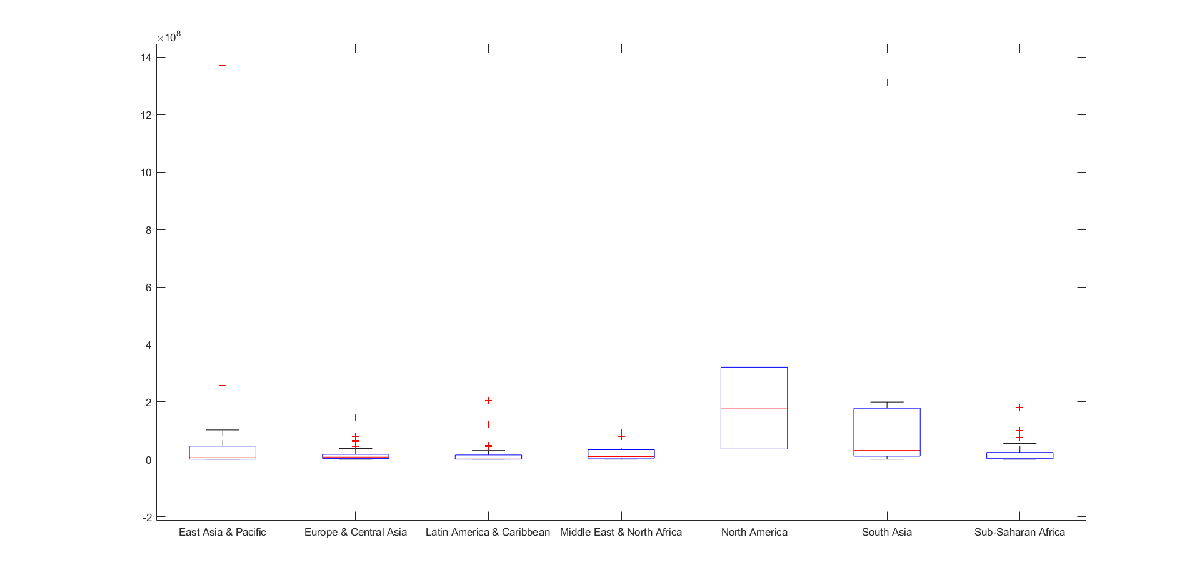

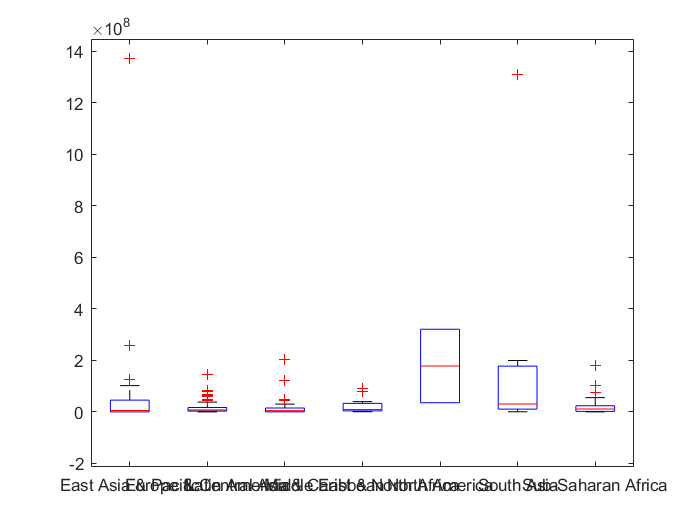

regions=PopulationsTotal.Region;
PopulationsTotal4=PopulationsTotal(:,4:end);
PopulationsTotal4=table2array(PopulationsTotal4);
boxplot(PopulationsTotal4(:,end),regions);

# Finally, export this file as pdf by clicking Save->Export to PDF